# Introduction to Synthetic Aperture Radar Using Python and MATLAB

## by Andy Harrison - © 2022 Artech House

### Example 2.12.4 Stripmap SAR Doppler Bandwidth

## Calculate the Doppler bandwidth

$B_d =2f_D =\frac{4v}{\lambda \;}\sin \left(\frac{\theta_a }{2}\right)\;\;\left(\textrm{Hz}\right)$   Equation (2.17)

% Clear the workspace
clear

% Velocity (m/s)
velocity = linspace(50, 300, 1e3);

% Operating frequency (Hz)
operating_frequency = 3e9; 

% Antenna beamwidth (deg)
beamwidth = [1, 2.5, 10];

% Calculate the Doppler bandwidth (Hz) 
for i = 1:length(beamwidth)
    doppler_bandwidth(i,:) = stripmap_doppler_bandwidth(velocity, operating_frequency, beamwidth(i));
end

## Plot the results

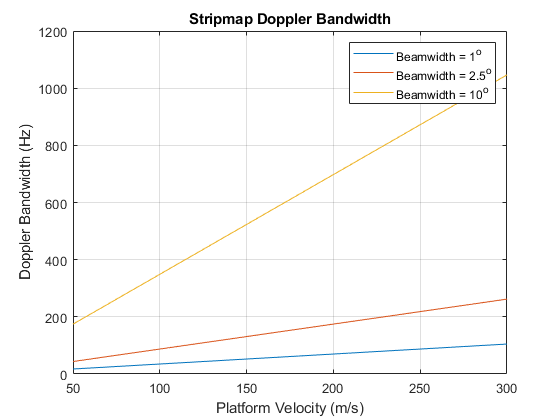

figure;
plot(velocity, doppler_bandwidth);
xlabel('Platform Velocity (m/s)')
ylabel('Doppler Bandwidth (Hz)');
title('Stripmap Doppler Bandwidth')
grid on
legend('Beamwidth = 1^o', 'Beamwidth = 2.5^o', 'Beamwidth = 10^o')